# for plotting csvs from physcial experiments

clc;
clear;
close all;

cd 'C:\Users\ahmed\Torsobot\Modelling\torsobot_dynamics\matlab\plotting'
addpath("../");
parameters;

## Get files

% Enter filename
filename = input("CSV filename: ", 's');
start_time = input("Start time (ms): ", 's');
start_time = str2double(start_time);

end_time = input("End time (ms): ", 's');
end_time = str2double(end_time);

% csv directory and file name
csv_directory  = "..\..\..\..\Code\ros2_ws\data_logs\csvs\";
csv_filename = csv_directory + filename + ".csv";

% yaml directory and file name
yaml_directory  = "..\..\..\..\Code\ros2_ws\data_logs\metadata\";
yaml_filename = yaml_directory + filename + ".yaml";

disp(["Reading file from: ", csv_filename])

    "Reading file from: "    "..\..\..\..\Code\ros2_ws\data_logs\csvs\.csv"



Iterate over Pitch

pitch = [15 20 30 40 45 50 60 65 70 75 80 85 90 95 100 105 110 115 120 130 140 150 160];
pitch = [45]

pitch = 45


directory = './mat_files/physical/'

directory = './mat_files/physical/'


for p = 1: length(pitch)
    p_filename = pitch(p) + "_file_data" + ".mat"
    full_file_path = directory + p_filename;
    file_data = load(full_file_path)

    filename= file_data.filename;
    start_time = file_data.start_time;
    end_time = file_data.end_time;

    csv_filename = csv_directory + filename + ".csv";

    yaml_directory  = "..\..\..\..\Code\ros2_ws\data_logs\metadata\";
    yaml_filename = yaml_directory + filename + ".yaml";

p_filename = "45_file_data.mat"

file_data = struct with fields:
      end_time: 100000
      filename: '2026-04-22_18-59-42_45'
    start_time: 13500


## get data from yaml

yaml_data = yaml.loadFile(yaml_filename);

desired_torso_pitch_deg = yaml_data.x___.ros__parameters.desired_torso_pitch_deg
controller = yaml_data.x___.ros__parameters.controller;
kp = yaml_data.x___.ros__parameters.kp;
ki = yaml_data.x___.ros__parameters.ki;
kd = yaml_data.x___.ros__parameters.kd;
wheel_max_torque = yaml_data.x___.ros__parameters.wheel_max_torque;
control_max_integral = yaml_data.x___.ros__parameters.control_max_integral;

torso_pitch_init = yaml_data.trial_values.torso_pitch_init;
wheel_rel_pos_init = yaml_data.trial_values.wheel_rel_pos_init;

disp(["Target torso pitch: ", desired_torso_pitch_deg, " deg"])

## Save file data

% mat_filename = "./mat_files/physical/" + num2str(desired_torso_pitch_deg) + "_file_data.mat";
% save(mat_filename, 'filename', 'start_time', 'end_time');

desired_torso_pitch_deg = 45

    "Target torso pitch: "    "45"    " deg"



## get data from csv

time_diff_s = 0.0050

ans = 50

changed time_diff_s


time_diff_s = 0.0100

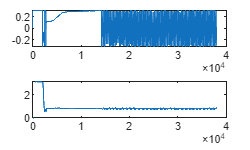

csv_data = readtable(csv_filename);

time = csv_data.timestamp;
time_diff_s = mean(diff(time))/1e9 % convert from ns to s

ceil(time_diff_s*10000)

if ceil(time_diff_s*10000) == 50
    disp("changed time_diff_s");

    %read every other value from table
    csv_data = csv_data(1:2:end, :);

    % confirm time_diff_s again
    time = csv_data.timestamp;
    time_diff_s = mean(diff(time))/1e9 % convert from ns to s
end

time = time - time(1); % get relative time from the first value
time = time/(1e6); % convert to ms

[~, start_idx] = min(abs(time - start_time));
[~, end_idx] = min(abs(time - end_time));

torso_pitch = csv_data.torso_pitch;
torso_pitch_rate = csv_data.torso_pitch_rate;
wheel_pos = csv_data.wheel_pos;
wheel_vel = csv_data.wheel_vel;
wheel_torque = csv_data.wheel_torque;
wheel_cmd_torque = csv_data.wheel_cmd_torque;
encoder_steps = csv_data.encoder_steps;
encoder_ang = csv_data.encoder_ang;
encoder_speed = csv_data.encoder_speed;


## plot original data for wheel_pos

% plot original data for wheel_pos
fig1 = figure(1);
subplot(2, 1, 1);
plot(time, wheel_pos);
subplot(2, 1, 2);
plot(time, torso_pitch);

num_steps_in_run = 83

## Start time to cutoff time


% from cutoff idx onwards
time = time(start_idx:end_idx);
torso_pitch = torso_pitch(start_idx:end_idx); 
torso_pitch_rate = torso_pitch_rate(start_idx:end_idx);
wheel_pos = wheel_pos(start_idx:end_idx);
wheel_vel_raw = wheel_vel(start_idx:end_idx);
wheel_torque = wheel_torque(start_idx:end_idx);
wheel_cmd_torque = wheel_cmd_torque(start_idx:end_idx);
encoder_steps = encoder_steps(start_idx:end_idx);
encoder_ang = encoder_ang(start_idx:end_idx);
encoder_speed = encoder_speed(start_idx:end_idx);

max_num_steps = 40

## recalculating wheel pos and velocity data

limit = pi/10;
total_width = pi/5;

wheel_rel_pos = encoder_ang - wheel_rel_pos_init;
wheel_pos_calc = wheel_rel_pos + (torso_pitch - torso_pitch_init);
wheel_pos_calc = wheel_pos_calc + limit;

% filter wheel_pos to remove chatter
wheel_pos_filt = medfilt1(wheel_pos_calc, 4, 'truncate');

% wrap position again
wheel_pos_wrap = mod(wheel_pos_filt + limit, total_width) - limit;

% find where impact occurs using diff and comparing it to a threshold
% difference (+/-2pi/10) on the wrapped angle
threshold = 0.5; % not exactly 2*pi/10
wheel_pos_diff = diff(wheel_pos_wrap);
pre_impact_idx = find(abs(wheel_pos_diff) > threshold);

num_steps_in_run = length(pre_impact_idx)

## get data for first *n* steps only

max_num_steps = 40
if pitch(p) == 160
    max_num_steps = 19
end

pre_impact_idx = pre_impact_idx(1:max_num_steps+1);

time = time(pre_impact_idx(1):pre_impact_idx(end));
time = time - time(1);

torso_pitch = torso_pitch(pre_impact_idx(1):pre_impact_idx(end)); 
torso_pitch_rate = torso_pitch_rate(pre_impact_idx(1):pre_impact_idx(end));
wheel_pos = wheel_pos(pre_impact_idx(1):pre_impact_idx(end));
wheel_pos_filt = wheel_pos_filt(pre_impact_idx(1):pre_impact_idx(end));
wheel_pos_wrap = wheel_pos_wrap(pre_impact_idx(1):pre_impact_idx(end));
wheel_vel_raw = wheel_vel_raw(pre_impact_idx(1):pre_impact_idx(end));
wheel_torque = wheel_torque(pre_impact_idx(1):pre_impact_idx(end));
wheel_cmd_torque = wheel_cmd_torque(pre_impact_idx(1):pre_impact_idx(end));
encoder_steps = encoder_steps(pre_impact_idx(1):pre_impact_idx(end));
encoder_ang = encoder_ang(pre_impact_idx(1):pre_impact_idx(end));
encoder_speed = encoder_speed(pre_impact_idx(1):pre_impact_idx(end));

% 
% adjust pre_impact_idx
pre_impact_idx = pre_impact_idx - pre_impact_idx(1) + 1;
time_impact = time(pre_impact_idx);

gravity_work_for_COT = 10.4486

## calculate wheel velocity again

perform center difference on all values and forward/backward difference on impact values

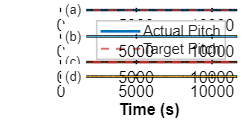

wheel_vel_calc = gradient(wheel_pos_wrap, time_diff_s); % center difference
% backward and forward differentiation at the pre and post impact points
for i= 1:length(pre_impact_idx)-1
    if i ~= 1
        % backward difference at pre-impact
        wheel_vel_calc(pre_impact_idx(i)) = (wheel_pos_filt(pre_impact_idx(i)) - wheel_pos_filt(pre_impact_idx(i)-1))/time_diff_s;
    end
    % forward difference at post-impact
    wheel_vel_calc(pre_impact_idx(i)+1) = (wheel_pos_filt(pre_impact_idx(i)+1) - wheel_pos_filt(pre_impact_idx(i)))/time_diff_s;
end

% very first value same as 2nd value
wheel_vel_calc(1) = wheel_vel_calc(2);

## Filtering wheel velocity data

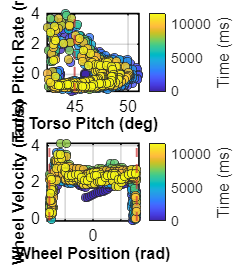

% median filter
wheel_vel_to_filter = wheel_vel_calc;
wheel_vel_med_fil = medfilt1(wheel_vel_to_filter, 3, 'truncate');

% butterworth filter
d1 = designfilt("lowpassiir", ...
    FilterOrder=2, ... 
    HalfPowerFrequency=40, ... 
    SampleRate=200, ...       
    DesignMethod="butter");
wheel_vel_butter_fil = filtfilt(d1, wheel_vel_to_filter);

% Savitzky-Golay
dt = time_diff_s;           
order = 3;           % cubic polynomial
window_length = 11;  

% 'g_' is a matrix containing the coefficients for different derivatives
[~, g_] = sgolay(order, window_length);

% We use g(:, 1) which holds the smoothing coefficients
pos_smoothed = conv(wheel_pos_filt, g_(:,1), 'same');

wheel_vel_sg = conv(wheel_pos_filt, flipud(g_(:,2)), 'same') / dt;

% our choice for velocity
wheel_vel = wheel_vel_med_fil;

## Average step velocity over a step

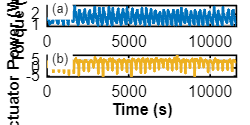

mean_step_vel = zeros(1, max_num_steps);
for i = 1:max_num_steps
    start_idx_for_mean = pre_impact_idx(i)+5;
    end_idx_for_mean = pre_impact_idx(i+1);

    start_time = time(start_idx_for_mean);
    end_time = time(end_idx_for_mean);

    mean_step_vel(i) = trapz(time(start_idx_for_mean:end_idx_for_mean), wheel_vel(start_idx_for_mean:end_idx_for_mean))/(end_time - start_time);
    % mean(wheel_vel(pre_impact_idx(i)+5 : pre_impact_idx(i+1))); % the 5 gets rid of the drop in velocity
end

## mid stance step velocity

find positon where wheel is closes to 0 angle

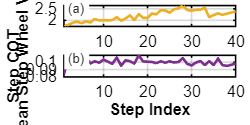

mid_stance_idx = find(wheel_pos_wrap(1:end-1) < 0 & wheel_pos_wrap(2:end) >= 0);
% mid_stance_idx = mid_stance_idx(1:end);
num_mid_stance = length(mid_stance_idx);
mid_stance_vel = zeros(1, num_mid_stance);

for i = 1:num_mid_stance
    mid_stance_vel(i) = wheel_vel(mid_stance_idx(i));
end

## Pre-collision step velocity

find positon where wheel is closes to 0 angle

precol_step_vel = zeros(1, max_num_steps);
for i = 1:max_num_steps
    idx_for_precol = pre_impact_idx(i+1);

    precol_step_vel(i) = wheel_vel(idx_for_precol);
end

## Torque and Power, COT

wheel_torque_filt = medfilt1(wheel_torque, 3, 'truncate');

power = wheel_torque_filt.*(wheel_vel-torso_pitch_rate);
power_filt = medfilt1(power, 3, 'truncate');

% clipped
power_filt_clipped = max(0, power_filt);

actuator_work = zeros(1, max_num_steps);
actuator_work_clipped = zeros(1, max_num_steps);

for i = 1:max_num_steps
    start_idx_for_mean = pre_impact_idx(i)+1;
    end_idx_for_mean = pre_impact_idx(i+1);

    start_time = time(start_idx_for_mean);
    end_time = time(end_idx_for_mean);

    actuator_work(i) = trapz(time(start_idx_for_mean:end_idx_for_mean), power_filt(start_idx_for_mean:end_idx_for_mean))/1e3;
    actuator_work_clipped(i) = trapz(time(start_idx_for_mean:end_idx_for_mean), power_filt_clipped(start_idx_for_mean:end_idx_for_mean))/1e3;

end

%COT calculations
step_length = sqrt(2*L^2 - 2*L*L*cos(2*pi/n));
gravity_work_for_COT = ((m+M)*g*step_length)

actuator_COT = actuator_work/gravity_work_for_COT;
actuator_COT_clipped = actuator_work_clipped/gravity_work_for_COT;

## Get step where limit velocity has been reached

mid stance and mean step velocity

% steps = 1:1:length(mean_step_vel);
% steps_log = 1./(steps);
% mean_step_vel_coeff = polyfit(steps_log, mean_step_vel, 1);
% mean_step_vel_fit = polyval(mean_step_vel_coeff, steps_log);
% 
% mid_stances = 1:length(mid_stance_vel);
% mid_stances_log = 1./(mid_stances);
% mid_stance_vel_coeff = polyfit(mid_stances_log, mid_stance_vel, 1);
% mid_stance_vel_fit = polyval(mid_stance_vel_coeff, mid_stances_log);
% 
% % filter velocity instead of fit
% mean_step_vel_filt = mean_step_vel;
% mean_step_vel_filt(3:end) = medfilt1(mean_step_vel(3:end), 5, 'truncate');
% mid_stance_vel_filt = mid_stance_vel;
% mid_stance_vel_filt(3:end) = medfilt1(mid_stance_vel(3:end), 5, 'truncate');
% 
% pt_threshold = 2; % percent
% % mean step vel
% mean_step_vel_diff = diff(mean_step_vel_filt);
% mean_step_pt_diff = mean_step_vel_diff./mean_step_vel_filt(1:end-1)*100; % percentage diff
% 
% limit_cycle_step_idx_mean_step_vel = find(abs(mean_step_pt_diff)<pt_threshold);
% limit_cycle_step_idx_mean_step_vel = limit_cycle_step_idx_mean_step_vel(1)
% 
% % mid stance vel
% mid_stance_vel_diff = diff(mid_stance_vel_filt);
% mid_stance_pt_diff = mid_stance_vel_diff./mid_stance_vel_filt(1:end-1)*100; % percentage diff
% 
% limit_cycle_step_idx_mid_stance_vel = find(abs(mid_stance_pt_diff)<pt_threshold);
% limit_cycle_step_idx_mid_stance_vel = limit_cycle_step_idx_mid_stance_vel(1)

## time data plotting

color_torso_pos = [0.00, 0.45, 0.74];  % Dark Blue
color_torso_vel = [0.30, 0.75, 0.93];  % Light Blue
color_wheel_pos = [0.85, 0.33, 0.10];  % Dark Orange/Rust
color_wheel_vel = [0.93, 0.69, 0.13];  % Golden Orange
color_target    = [0.80, 0.20, 0.20];  % Muted Red for target ylines

% plot in deg
torso_pitch_deg = rad2deg(torso_pitch); 

fig2 = figure(2);
tiledlayout(4, 1, 'TileSpacing', 'compact', 'Padding', 'compact');

t = time;

nexttile;
plot(t, torso_pitch_deg, 'Color', color_torso_pos, 'LineWidth', 2); 
hold on;
yline(desired_torso_pitch_deg, "--", 'Color', color_target, 'LineWidth', 1.5); 

xlim([t(1), t(end)]);
ylim auto;
% ylim([0.80*min(torso_pitch), 1.20*max(torso_pitch)])

ylabel('Torso Pitch (deg)');

legend('Actual Pitch', 'Target Pitch', 'Location', 'northeast');

grid on;

text(0.02, 0.85, '(a)', 'Units', 'normalized', ...
    'FontSize', 10, 'FontName', 'Helvetica', ...
    'BackgroundColor', 'w', 'EdgeColor', 'none'); % 'w' = white background, 'k' = black border

hold off;

nexttile;
plot(t, torso_pitch_rate, 'Color', color_torso_vel, 'LineWidth', 2);
hold on;

xlim([t(1), t(end)]);
ylim auto;
% ylim([1.20*min(torso_pitch_rate), 1.20*max(torso_pitch_rate)])

ylabel('Torso Pitch Rate (rad/s)');

grid on;

text(0.02, 0.85, '(b)', 'Units', 'normalized', ...
    'FontSize', 10, 'FontName', 'Helvetica', ...
    'BackgroundColor', 'w', 'EdgeColor', 'none'); % 'w' = white background, 'k' = black border

hold off;

nexttile;
plot(t, wheel_pos_wrap, 'Color', color_wheel_pos, 'LineWidth', 2); 
hold on;
yline(-pi/10, '--', 'Color', color_target, 'LineWidth', 1.5);
yline(pi/10, '--', 'Color', color_target, 'LineWidth', 1.5);

xlim([t(1), t(end)]);
ylim([-0.33, 0.33])

ylabel("Wheel Position (rad)");

grid on;

text(0.02, 0.85, '(c)', 'Units', 'normalized', ...
    'FontSize', 10, 'FontName', 'Helvetica', ...
    'BackgroundColor', 'w', 'EdgeColor', 'none'); % 'w' = white background, 'k' = black border

hold off;


nexttile;
plot(t, wheel_vel, 'Color', color_wheel_vel, 'LineWidth', 2); 
hold on;

xlim([t(1), t(end)]);
ylim auto;
% ylim([0.80*min(wheel_vel), 1.20*max(wheel_vel)])

ylabel("Wheel Velocity (rad/s)");
xlabel("Time (s)");

grid on; 

text(0.02, 0.85, '(d)', 'Units', 'normalized', ...
    'FontSize', 10, 'FontName', 'Helvetica', ...
    'BackgroundColor', 'w', 'EdgeColor', 'none'); % 'w' = white background, 'k' = black border

hold off;

format_my_plot(10, 5);

% save figures
filename = "State_vs_Time_" +  num2str(desired_torso_pitch_deg) + ".png";

save_directory  = "..\matlab_plots\Physical\";
save_filename = save_directory + filename;

exportgraphics(gcf, save_filename, 'Resolution', 600);

## scatter plot/phase portrait

fig3 = figure(3);

tiledlayout(2, 1, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile;
scatter(torso_pitch_deg, torso_pitch_rate, 40, t, 'o', 'filled', ...
    'MarkerEdgeColor', [0.15 0.15 0.15], ... % Thin dark edge for definition
    'MarkerFaceAlpha', 0.8, ...              % Slight transparency for overlap
    'LineWidth', 0.5);

colormap('parula');           % The standard Blue-to-Yellow gradient
cb = colorbar;                % Creates the colorbar on the right
cb.Label.String = 'Time (ms)'; % Adds the label to the colorbar
cb.Label.FontSize = 12;

hold on;
xline(desired_torso_pitch_deg, "--", 'Color', color_target, 'LineWidth', 1.5); 

xlim auto;
ylim auto;

xlabel("Torso Pitch (deg)")
ylabel('Torso Pitch Rate (rad/s)');

grid on;

hold off;

nexttile;
scatter(wheel_pos, wheel_vel, 40, t, 'o', 'filled', ...
    'MarkerEdgeColor', [0.15 0.15 0.15], ... % Thin dark edge for definition
    'MarkerFaceAlpha', 0.8, ...              % Slight transparency for overlap
    'LineWidth', 0.5);

colormap('parula');           % The standard Blue-to-Yellow gradient
cb = colorbar;                % Creates the colorbar on the right
cb.Label.String = 'Time (ms)'; % Adds the label to the colorbar
cb.Label.FontSize = 12;

hold on;
xline([-pi/10, pi/10], "--", 'Color', color_target, 'LineWidth', 1.5); 

xlim(0.33*[-1, 1]);
ylim auto;

xlabel("Wheel Position (rad)")
ylabel('Wheel Velocity (rad/s)');

grid on;

hold off;

format_my_plot(6.5, 7);

% save figures
filename = "phase_plot" +  num2str(desired_torso_pitch_deg) + ".png";

save_directory  = "..\matlab_plots\Physical\";
save_filename = save_directory + filename;

exportgraphics(gcf, save_filename, 'Resolution', 600);

## Torque and Power Plots

color_wheel_torque = [0.00, 0.45, 0.74];  % Dark Blue
color_wheel_power = [0.93, 0.69, 0.13];  % Golden Orange

fig4 = figure(4);
tiledlayout(2, 1, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile;
plot(t, wheel_torque_filt, 'Color', color_wheel_torque, 'LineWidth', 2); 
hold on;

xlim([t(1), t(end)]);
ylim auto;

ylabel('Torque (Nm)');

grid on;

text(0.02, 0.85, '(a)', 'Units', 'normalized', ...
    'FontSize', 10, 'FontName', 'Helvetica', ...
    'BackgroundColor', 'w', 'EdgeColor', 'none'); % 'w' = white background, 'k' = black border

hold off;

nexttile;
plot(t, power_filt, 'Color', color_wheel_power, 'LineWidth', 2); 
hold on;

xlim([t(1), t(end)]);
ylim auto;

xlabel("Time (s)");
ylabel('Actuator Power (W)');

grid on;

text(0.02, 0.85, '(b)', 'Units', 'normalized', ...
    'FontSize', 10, 'FontName', 'Helvetica', ...
    'BackgroundColor', 'w', 'EdgeColor', 'none'); % 'w' = white background, 'k' = black border

hold off;

format_my_plot(10, 5);

% save figures
filename = "actuator_effort_" +  num2str(desired_torso_pitch_deg) + ".png";

save_directory  = "..\matlab_plots\Physical\";
save_filename = save_directory + filename;

exportgraphics(gcf, save_filename, 'Resolution', 600);

## Mean step velocity and COT

fig5 = figure(5);

color_actuator_COT = [0.49, 0.18, 0.56];  % Plum/Purple

step_idx = 1:max_num_steps;

fig6 = figure(6);
tiledlayout(2, 1, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile;
plot(step_idx, mean_step_vel, 'Color', color_wheel_vel, 'LineWidth', 2); 
hold on;

xlim([step_idx(1), step_idx(end)]);
ylim auto;

ylabel('Mean Step Wheel Velocity (rad/s)');

grid on;

text(0.02, 0.85, '(a)', 'Units', 'normalized', ...
    'FontSize', 10, 'FontName', 'Helvetica', ...
    'BackgroundColor', 'w', 'EdgeColor', 'none'); % 'w' = white background, 'k' = black border

hold off;

nexttile;
plot(step_idx, actuator_COT_clipped, 'Color', color_actuator_COT, 'LineWidth', 2); 
hold on;

xlim([step_idx(1), step_idx(end)]);
ylim auto;

xlabel('Step Index')
ylabel('Step COT');

grid on;

text(0.02, 0.85, '(b)', 'Units', 'normalized', ...
    'FontSize', 10, 'FontName', 'Helvetica', ...
    'BackgroundColor', 'w', 'EdgeColor', 'none'); % 'w' = white background, 'k' = black border

hold off;

format_my_plot(10, 5);

% save figures
filename = "step_to_step_" +  num2str(desired_torso_pitch_deg) + ".png";

save_directory  = "..\matlab_plots\Physical\";
save_filename = save_directory + filename;

exportgraphics(gcf, save_filename, 'Resolution', 600);

## Save mean values from all steps

mat_filename = "./mat_files/physical/" + num2str(desired_torso_pitch_deg) + "_mean_step_data.mat";
save(mat_filename, "mean_step_vel", "actuator_COT", "actuator_COT_clipped");

## Save mean values from last n steps

save_steps = 5;
mean_step_vel_save = mean(mean_step_vel(end-save_steps:end));
% mid_stance_vel_save = mean(mid_stance_vel_filt(end-save_steps:end));
mean_step_work_save = mean(actuator_work(end-save_steps:end));
mean_step_work_clipped_save = mean(actuator_work_clipped(end-save_steps:end));
precol_step_vel_save = mean(precol_step_vel(end-save_steps:end));

mat_filename = "./mat_files/physical/" + num2str(desired_torso_pitch_deg) + "_end_steps_data.mat";
save(mat_filename, "mean_step_vel_save", "precol_step_vel_save", "mean_step_work_save", "mean_step_work_clipped_save");

End of for loop

end

## functions

function encoder_ang =  encoderCountsToRad(local_signed_encoder_steps) 
  encoder_ang = (local_signed_encoder_steps) / (2048*4) * 2 * PI;

end